1.

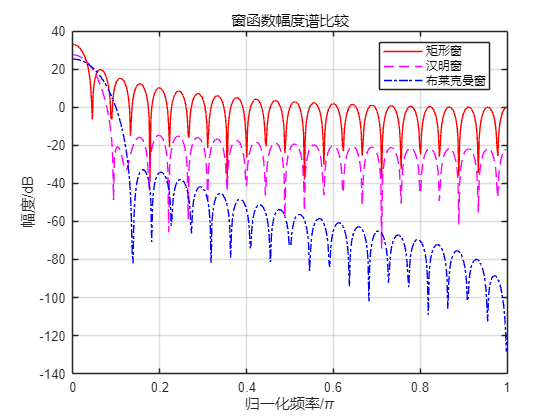

clear all;
N = 45;
% 矩形窗
wn1 = boxcar(N);
% 汉明窗
wn2 = hamming(N);
% 布莱克曼窗
wn3 = blackman(N);

[h1, w1] = freqz(wn1, 1);
[h2, w2] = freqz(wn2, 1);
[h3, w3] = freqz(wn3, 1);

h1_dB = 20*log10(abs(h1));
h2_dB = 20*log10(abs(h2));
h3_dB = 20*log10(abs(h3));

figure;
plot(w1/pi, h1_dB, 'r-', w2/pi, h2_dB, 'm--', w3/pi, h3_dB, 'b-.');
xlabel('归一化频率/\pi');
ylabel('幅度/dB');
title('窗函数幅度谱比较');
legend('矩形窗', '汉明窗', '布莱克曼窗', 'Location', 'best');
grid on;

2.

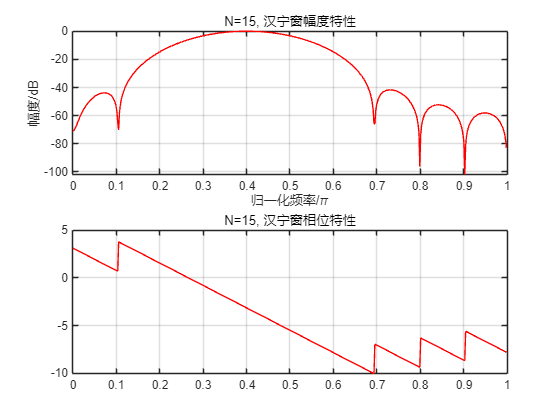

clear all;
N1 = 15;
wn = [0.3, 0.5];
window = hanning(N1+1);
b1 = fir1(N1, wn, window);
[h1, w] = freqz(b1);
figure;
subplot(2,1,1);
plot(w/pi, 20*log10(abs(h1)), 'r');
xlabel('归一化频率/\pi'); ylabel('幅度/dB');
title('N=15, 汉宁窗幅度特性');
grid on;
subplot(2,1,2);
plot(w/pi, unwrap(angle(h1)), 'r'); 
title('N=15, 汉宁窗相位特性');
grid on;

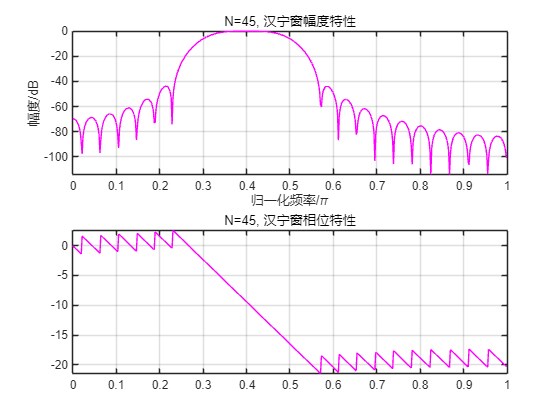


N2 = 45;
wn2 = [0.3, 0.5];
window2 = hanning(N2+1);
b2 = fir1(N2, wn2, window2);
[h2, w2] = freqz(b2);
figure;
subplot(2,1,1);
plot(w2/pi, 20*log10(abs(h2)), 'm');
xlabel('归一化频率/\pi'); ylabel('幅度/dB');
title('N=45, 汉宁窗幅度特性');
grid on;
subplot(2,1,2);
plot(w2/pi, unwrap(angle(h2)), 'm'); 
title('N=45, 汉宁窗相位特性');
grid on;

3.

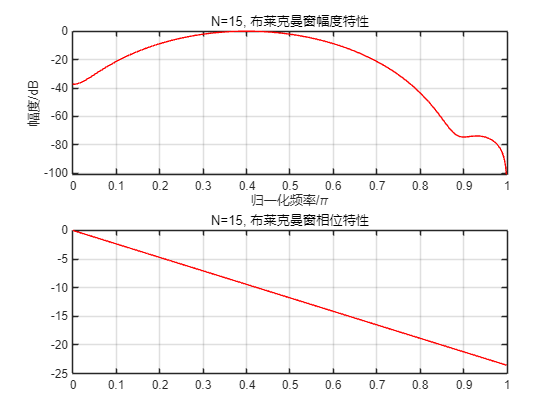

clear all;
N1 = 15;
wn = [0.3, 0.5];
window = blackman(N1+1);
b1 = fir1(N1, wn, window);
[h1, w] = freqz(b1);
figure;
subplot(2,1,1);
plot(w/pi, 20*log10(abs(h1)), 'r');
xlabel('归一化频率/\pi'); ylabel('幅度/dB');
title('N=15, 布莱克曼窗幅度特性');
grid on;
subplot(2,1,2);
plot(w/pi, unwrap(angle(h1)), 'r'); 
title('N=15, 布莱克曼窗相位特性');
grid on;

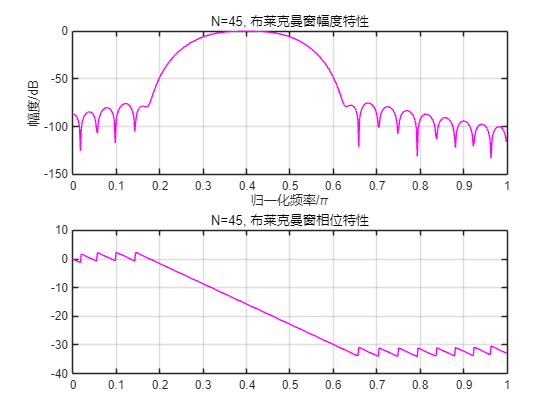


N2 = 45;
wn2 = [0.3, 0.5];
window2 = blackman(N2+1);
b2 = fir1(N2, wn2, window2);
[h2, w2] = freqz(b2);
figure;
subplot(2,1,1);
plot(w2/pi, 20*log10(abs(h2)), 'm');
xlabel('归一化频率/\pi'); ylabel('幅度/dB');
title('N=45, 布莱克曼窗幅度特性');
grid on;
subplot(2,1,2);
plot(w2/pi, unwrap(angle(h2)), 'm'); 
title('N=45, 布莱克曼窗相位特性');
grid on;

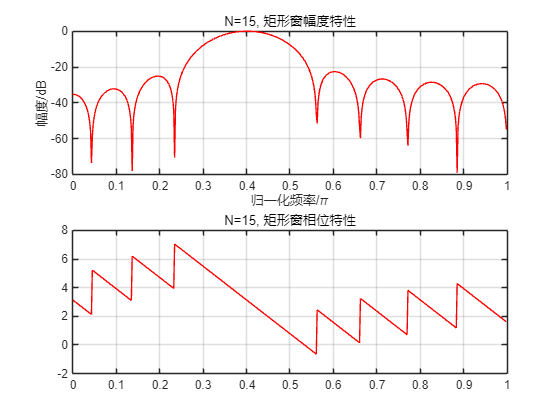

clear all;
N1 = 15;
wn = [0.3, 0.5];
window = boxcar(N1+1);
b1 = fir1(N1, wn, window);
[h1, w] = freqz(b1);
figure;
subplot(2,1,1);
plot(w/pi, 20*log10(abs(h1)), 'r');
xlabel('归一化频率/\pi'); ylabel('幅度/dB');
title('N=15, 矩形窗幅度特性');
grid on;
subplot(2,1,2);
plot(w/pi, unwrap(angle(h1)), 'r'); 
title('N=15, 矩形窗相位特性');
grid on;

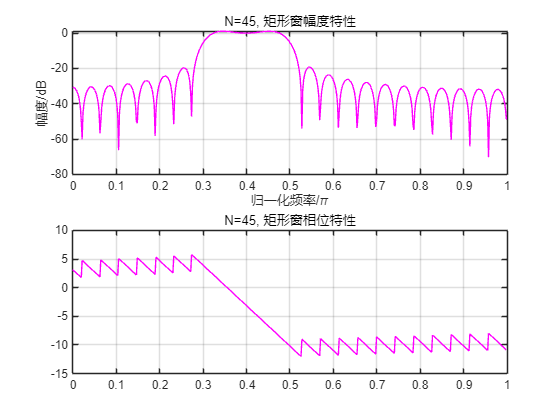


N2 = 45;
wn2 = [0.3, 0.5];
window2 = boxcar(N2+1);
b2 = fir1(N2, wn2, window2);
[h2, w2] = freqz(b2);
figure;
subplot(2,1,1);
plot(w2/pi, 20*log10(abs(h2)), 'm');
xlabel('归一化频率/\pi'); ylabel('幅度/dB');
title('N=45, 矩形窗幅度特性');
grid on;
subplot(2,1,2);
plot(w2/pi, unwrap(angle(h2)), 'm'); 
title('N=45, 矩形窗相位特性');
grid on;

4.

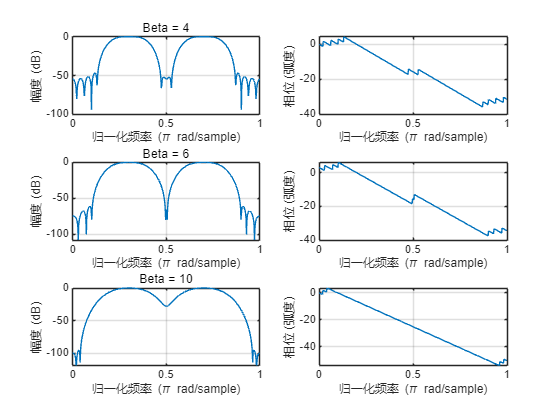

N = 40;
beta = [4, 6, 10];
figure; % 创建一个图形窗口
for i = 1:length(beta)
    window = kaiser(N+1, beta(i));
    h = fir1(N, [0.2, 0.4, 0.6, 0.8], 'bandpass', window);
    [h1, w1] = freqz(h, 1);
    
    subplot(3,2, i*2-1); % 选择子图位置
    plot(w1/pi, 20*log10(abs(h1)));
    title(['Beta = ', num2str(beta(i))]);
    xlabel('归一化频率 (\pi rad/sample)');
    ylabel('幅度 (dB)');
    grid on;
    subplot(3,2,i*2); % 选择子图位置
    plot(w1/pi, unwrap(angle(h1)));
    xlabel('归一化频率 (\pi rad/sample)');
    ylabel('相位 (弧度)');
    grid on;
end

5.

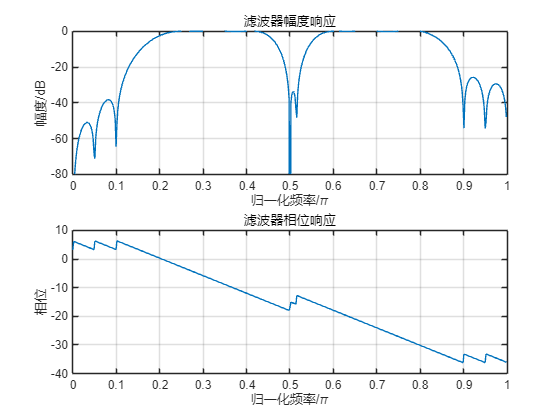

clc; 
clear;
N = 40;
Hk = [zeros(1,3) 0.5 ones(1,5) 0.5 zeros(1,1) 0.5 ones(1,5) 0.5 ...
       zeros(1,5) -0.5 -ones(1,5) -0.5 zeros(1,1) -ones(1,5) -0.5 zeros(1,3)];
k = 0:N-1;
thetak = -k * 2 * pi / N * ((N-1) / 2);
hn = real(ifft(Hk .* exp(1j * thetak)));
[h, w] = freqz(hn, 1);
figure;
subplot(211);
plot(w/pi, 20*log10(abs(h)));
grid on;
axis([0 1 -80 0]);
xlabel('归一化频率/\pi'); ylabel('幅度/dB');
title('滤波器幅度响应');

subplot(212);
plot(w/pi, unwrap(angle(h)));
xlabel('归一化频率/\pi'); ylabel('相位');
grid on;
title('滤波器相位响应');

6.

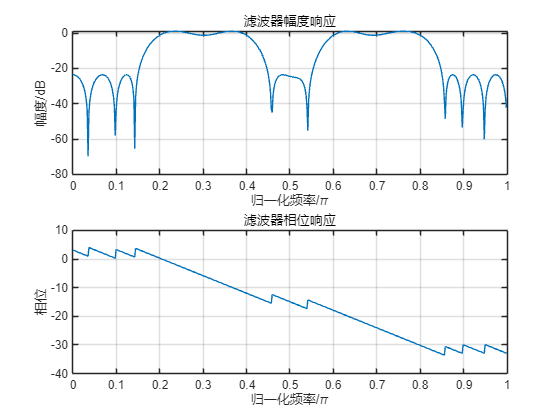

clc; clear;

N = 40;

f = [0, 0.15, 0.2, 0.4, 0.45, 0.55, 0.6, 0.8, 0.85, 1];
a = [0, 0, 1, 1, 0, 0, 1, 1, 0, 0];
wt=[2 1 2 1 2];
h = remez(N-1, f, a,wt);

[h1, w1] = freqz(h, 1);
figure;
subplot(2,1,1);
plot(w1/pi, 20*log10(abs(h1)));
xlabel('归一化频率/\pi');
ylabel('幅度/dB');
title('滤波器幅度响应');
grid on;

subplot(2,1,2);
plot(w1/pi, unwrap(angle(h1)));
xlabel('归一化频率/\pi');
ylabel('相位');
title('滤波器相位响应');
grid on;

7.

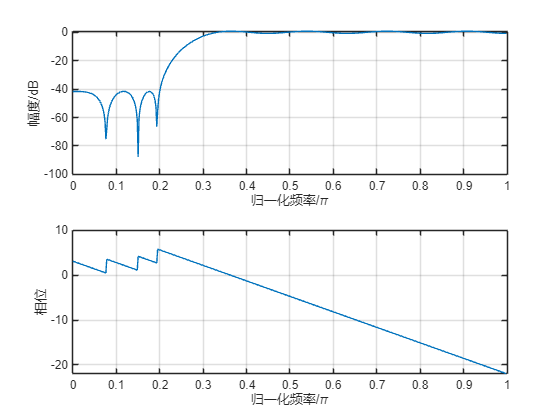

clc;
clear;

fs = 5000;
f = [500, 800];
a = [0, 1];
dev = [10^(-40/20), 1-10^(-1/20)];
[M, fpts, mag, wt] = remezord(f, a, dev, fs);
b = remez(M, fpts, mag, wt);
[h, w] = freqz(b, 1);
figure;
subplot(2, 1, 1);
plot(w/pi, 20*log10(abs(h)));
xlabel('归一化频率/\pi');
ylabel('幅度/dB');
grid on;
subplot(2, 1, 2);
plot(w/pi, unwrap(angle(h)));
xlabel('归一化频率/\pi');
ylabel('相位');
grid on;